x=[3,1,5,3]

x =      3     1     5     3


y=[0,-2,6,0]

y =      0    -2     6     0


z=[3,4,8,3]

z =      3     4     8     3


P=[3 1 5 3;0 -2 6 0;3 4 8 3]

P =      3     1     5     3
     0    -2     6     0
     3     4     8     3


plot3(x,y,z,'r')
%Proyeccion en el plano XY
%Matriz de Proyeccion
hold on 
A=[1 0 0;0 1 0;0 0 0]

A =      1     0     0
     0     1     0
     0     0     0


P1=A*P

P1 =      3     1     5     3
     0    -2     6     0
     0     0     0     0


x1=P1(1,:)

x1 =      3     1     5     3


y1=P1(2,:)

y1 =      0    -2     6     0


z1=P1(3,:)

z1 =      0     0     0     0


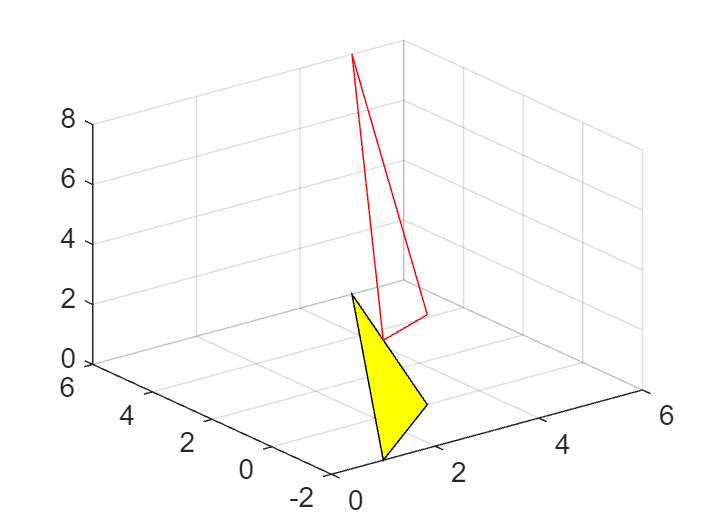

plot3(x1,y1,z1,'b')
fill3(x1,y1,z1,'y')
grid on



xyz=[1; 1; 1]

xyz =      1
     1
     1


m=30

m = 30

nxyz = rotacion_x(30,xyz)

nxyz =     1.0000
    0.3660
    1.3660


nxyz = rotacion_y(60,nxyz)

m = 60

nxyz =     1.6830
    0.3660
   -0.1830


# Funciones de Rotación

function cord=rotacion_x(m,xyz)
angu=(m/180)*pi; % Angulo de rotacion
C=cos(angu);
S=sin(angu);
%Rotacion alrededor del eje X
Rx=[1 0 0;0 C  -S; 0 S C];
cord=Rx*xyz;
end

function cord=rotacion_y(m,xyz)
angu=(m/180)*pi; % Angulo de rotacion
C=cos(angu);
S=sin(angu);
%Rotacion alrededor del eje Y
Ry=[C  0 S; 0 1 0; -S 0 C];
cord=Ry*xyz;
end

function cord=rotacion_z(m,xyz)
angu=(m/180)*pi; % Angulo de rotacion
C=cos(angu);
S=sin(angu);
%Rotacion alrededor del eje Z
Rz=[C -S 0;S C 0; 0 0 1];
cord=Rz*xyz;
end